% 清空
clc;
clear;

% data path
data_path = 'D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared';
% saving path
save_path = ['D:\Matlab_data_file\EEGdata\var',filesep];

% 定义一个对象用于存放不同marker信息
% 'CS+：112'
% 'GS1：113'
% 'GS2：114'
% 'GS3：115'
% 'GS4：116'
% 'GS5：117'
% 'GS6：118'
% 'GS7：119'
% 'GS8：120'
% 'CS-：121'
cond = {'112','113','114','115','116','117','118','119','120','121'};

% 将每个被试平均后的数据【分不同条件】合成一个数据集
for i = 1:4
    try
        % 拼接被试的文件名
        data_name = ['sub',num2str(i),'.set'];
        % 导入该被试数据
        EEG = pop_loadset('filename',data_name,'filepath',data_path);
        % 检查EEG数据是否完好
        EEG = eeg_checkset(EEG);
        for j = 1: length(cond)% 对于每个条件下的tiral
            EEG_new = pop_epoch(EEG,cond(j),[-1,2],'newname','sub_cond_lv_data','epochinfo','yes');
            EEG_new = eeg_checkset(EEG_new);
            % 基线矫正
            EEG_new = pop_rmbase(EEG_new,[-1000 0]);
            EEG_new = eeg_checkset(EEG_new);
            % EEG_new.data是一个三维数据集：channel × timepoint × trial
            % 做trial水平上的均值，降维，得到二维数据集，然后添加被试变量i，条件变量j，组成四维数据集
            % EEG_avg：subject × condition × channel × timepoint
            EEG_avg(i,j,:,:) = squeeze(mean(EEG_new.data,3));
        end
    catch ME
    end
end

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub1.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():41 epochs selected
Epoching...
pop_epoch():41 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():17 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():16 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():17 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():16 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():41 epochs selected
Epoching...
pop_epoch():36 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub2.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():21 epochs selected
Epoching...
pop_epoch():21 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub3.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub4.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():17 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():11 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():13 epochs selected
Epoching...
pop_epoch():11 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():22 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


% 把EEG_avg变量保存成group_level_erp.mat
save([save_path,'group_cond_lv_erp.mat'],"EEG_avg");

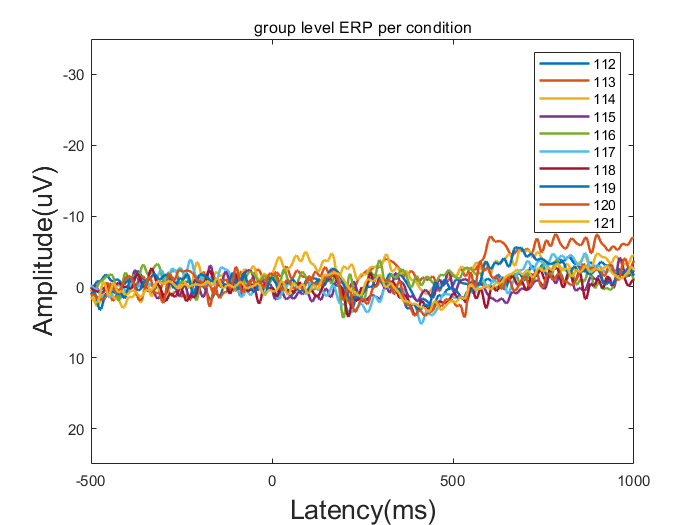

% 绘制组水平的erp曲线（分不同刺激）
% 设定感兴趣的电极（以AF4为例）
COI = 5;

% 提取所有被试在这个电极上的数据,并且做被试水平上的平均
mean_data = squeeze(mean(EEG_avg(:,:,COI,:),1));

% 生成一个空画布
figure;

% 绘制
plot(EEG.times,mean_data,'LineWidth',1.5);
set(gca,'YDir','reverse');
axis([-500 1000 -35 25]);
title('group level ERP per condition');
xlabel('Latency(ms)','FontSize',16);
ylabel('Amplitude(uV)','FontSize',16);
legend(cond)

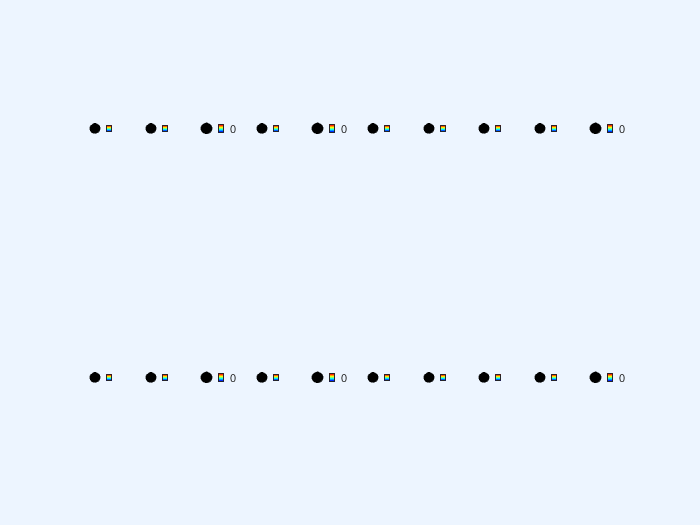

% 绘制组水平的地形图
% 通过erp曲线图确定感兴趣成分的峰值时间，并选择合适的半径作为计算区间
N1_peak = 280;
P1_peak = 200;

% 获取与上述时间区间相对应的索引
n_idx = time_intv_index(EEG,N1_peak,10);
p_idx = time_intv_index(EEG,P1_peak,10);

% EEG_avg是一个四维数据集，subject × condition × channel × timepoint
% 提取所有被试，所有条件，所有通道，感兴趣的时间区间内的数据
% 对这个时间区间内的所有数据进行平均，然后对所有被试进行平均，然后挤压多余的维度
% 得到的数据是在该时间区间内，内各个通道每种刺激下，每个被试平均的平均能量值
n_amplitude = squeeze(mean(mean(EEG_avg(:,:,:,n_idx),4),1));
p_amplitude = squeeze(mean(mean(EEG_avg(:,:,:,p_idx),4),1));

% 空画布
figure;

for i = 1:10
    % 提取该刺激所有通道上的数据（n_amplitude：condition × channel）
    % 2行10列第i张（N1图×10种刺激）
    subplot(2,10,i);
    topoplot(n_amplitude(i,:),EEG.chanlocs,'maplimits',[-15,15]);
    colorbar;
    % 2行10列第i+10张（P1图×10种刺激）
    subplot(2,10,i+10);
    topoplot(p_amplitude(i,:),EEG.chanlocs,'maplimits',[-15,15]);
    colorbar;
end

function idx = time_intv_index(data,t,len)% 计算时间点索引的函数
    % data-EEG struct
    % t-time point of interest
    % len - diameter of time range to be averaged
    t_min = t - len;
    t_max = t + len;
    idx = find(data.times>t_min & data.times<t_max);
end